# Evaluation of Forecast Hub for German and Polish state-level COVID-19 forecasts

**[Updated Jan 3rd, 2020]**

The following shows the mean absolute error of forecasts produced by various teams for Germany and Poland and their states and voivodeships, respectively.

The forecasting teams submit their forecasts to [https://github.com/KITmetricslab/covid19-forecast-hub-de](https://github.com/KITmetricslab/covid19-forecast-hub-de)

These forecasts can be visualized at [https://kitmetricslab.github.io/forecasthub/forecast](https://kitmetricslab.github.io/forecasthub/forecast)

All the errors used below are derived from the files at: [https://github.com/KITmetricslab/covid19-forecast-hub-de/tree/master/evaluation](https://github.com/KITmetricslab/covid19-forecast-hub-de/tree/master/evaluation)

% Load latest KIT evaluations
warning off;
urlwrite('https://raw.githubusercontent.com/KITmetricslab/covid19-forecast-hub-de/master/evaluation/evaluation-ECDC.csv', 'dummy.csv');
kiteval = readtable('dummy.csv');


% Extract lists of methods, places, and days
kiteval.model = strrep(kiteval.model, '-', '_');
methods = unique(kiteval.model);
countries = unique(kiteval.location);
base_days = unique(kiteval.timezero);


% Initialize error matrices
max_ahead = 4;
for mm=1:length(methods)
    eval(['case_' methods{mm} '= nan(length(base_days), length(countries), max_ahead);']);
    eval(['death_' methods{mm} '= nan(length(base_days), length(countries), max_ahead);']);
end

% Prepare error matrices
c_map = containers.Map(countries, (1:length(countries)));
m_map = containers.Map(methods, (1:length(methods)));
for tidx = 1:height(kiteval)
    tt = find(base_days == kiteval.timezero(tidx));
    cc = c_map(kiteval.location{tidx});
    mm = m_map(kiteval.model{tidx});
    thisval = kiteval.ae(tidx);
    if contains(kiteval.target{tidx}, 'inc case')
        ahead = str2double(kiteval.target{tidx}(1));
        if ahead>=1 && ahead <=4
            eval(['case_' methods{mm} '(tt, cc, ahead) = thisval;']);
        end
    elseif contains(kiteval.target{tidx}, 'inc death')
        ahead = str2double(kiteval.target{tidx}(1));
        if ahead>=1 && ahead <=4
            eval(['death_' methods{mm} '(tt, cc, ahead) = thisval;']);
        end
    end
%     if mod(tidx, 1000)==0
%         fprintf('.');
%     end
end

## Errors for Poland Voivodeship death forecasts

Jump to: Poland voivodeships death forecasts; Poland voivodeships case forecasts; Germany states death forecasts; Germany states case forecasts; Poland+Germany country-level death forecasts; Poland+Germany country-level case forecasts;

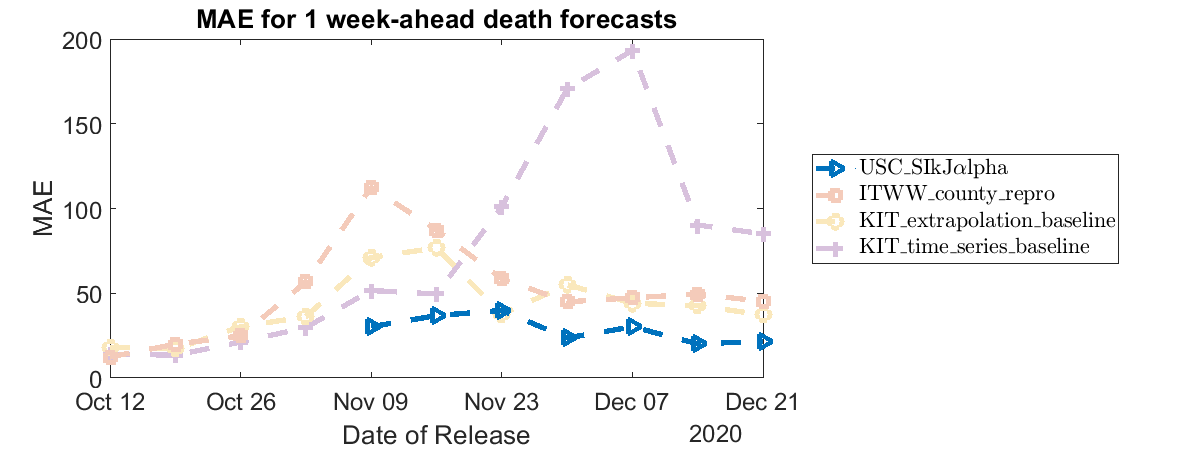

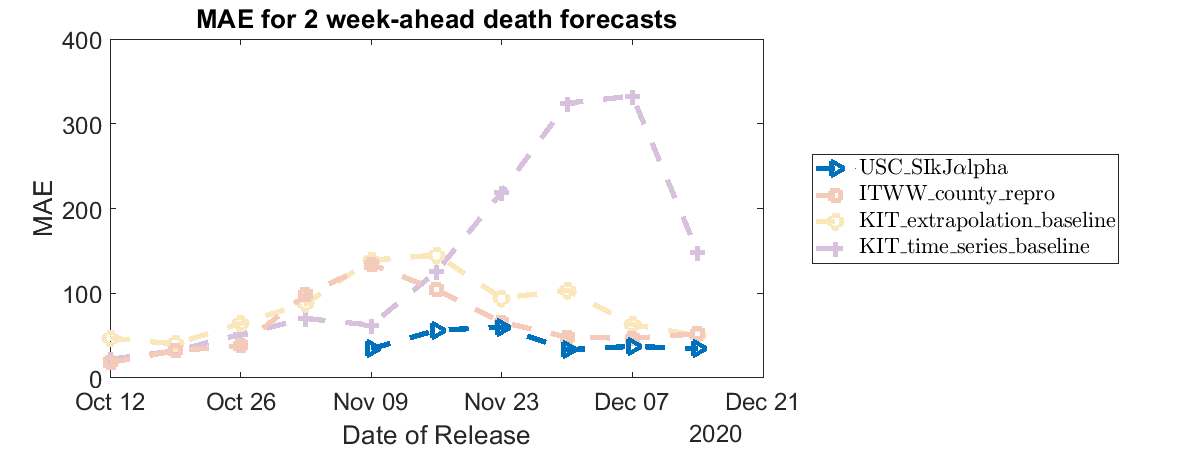

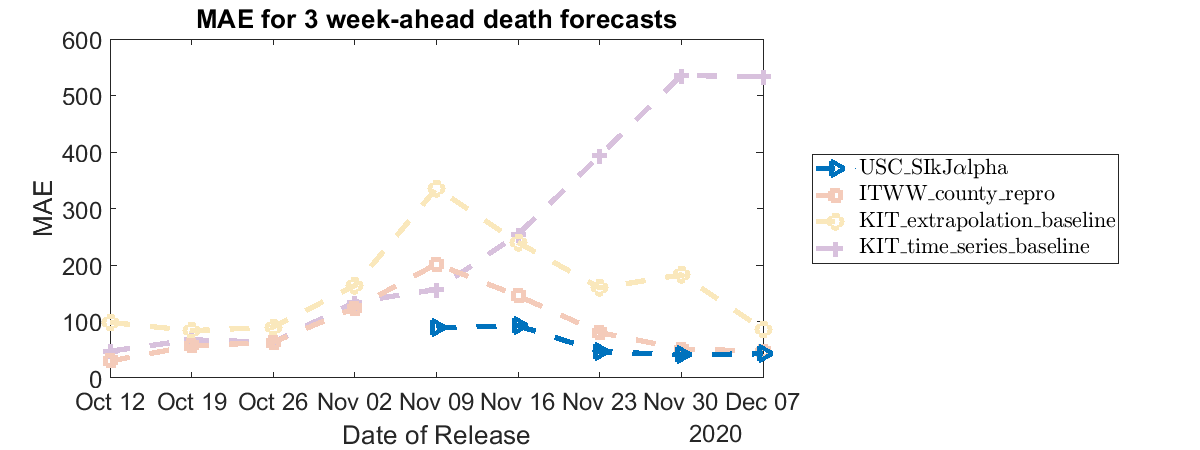

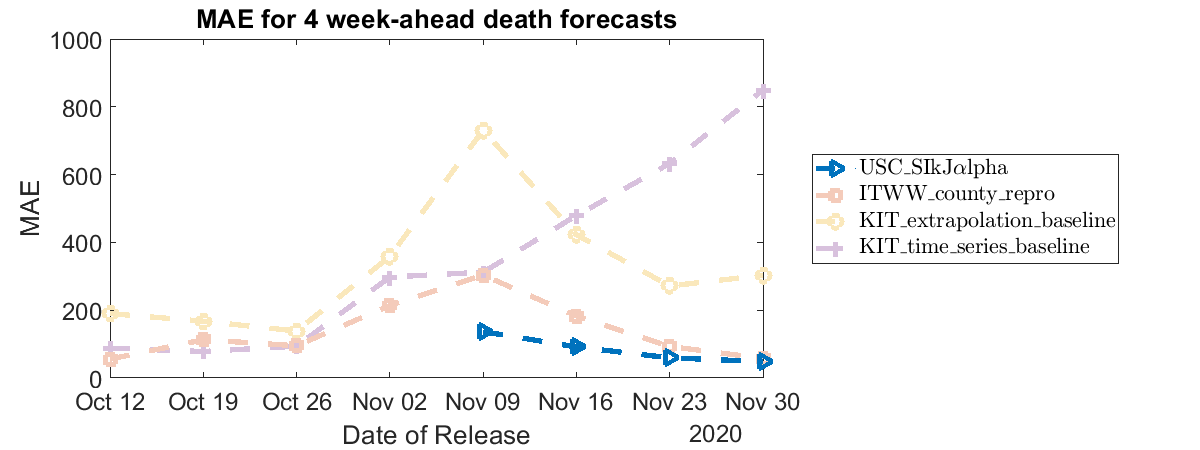

all_marks = {'o','+','*','.','x','s','d','^','v','>','<','p','h'};

sel_regs = contains(countries, 'PL7')|contains(countries, 'PL8');
highlight_idx = 0.3*ones(length(methods), 1);
sel_methods = [find(startsWith(methods, 'USC')); find(contains(methods, 'hub'))];
highlight_idx(sel_methods) = 1;
reorder_idx = [sel_methods; find(highlight_idx<1)];

for aidx = 1:4
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    ll = {};
    hh = zeros(length(methods), 1);
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['all_error = death_' methods{mm} ';']);
        errs = nanmean(squeeze(all_error(:, sel_regs, aidx)), 2);
        nnanidx = ~isnan(errs);
        if sum(nnanidx)<1
            continue;
        end
        Tx = base_days;
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{1+mod(mm, 13)}, 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10);
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        hh(mm1) = p1;
        hold on;
        ll = [ll; methods{mm}];
    end
    title(['MAE for ' num2str(aidx) ' week-ahead death forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    
    hold off;
    ll = strrep(ll, '_', '\_');
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    set(gca, 'Children', fliplr(hh(hh>0)));
    ll = get(legend(), 'String');
    plots = flipud(get(gca, 'children'));
    neworder = length(ll):-1:1;
    legend(plots(neworder), ll(neworder)); 
end

## Errors for Poland voivodeship case forecasts

Jump to: Poland voivodeships death forecasts; Poland voivodeships case forecasts; Germany states death forecasts; Germany states case forecasts; Poland+Germany country-level death forecasts; Poland+Germany country-level case forecasts;

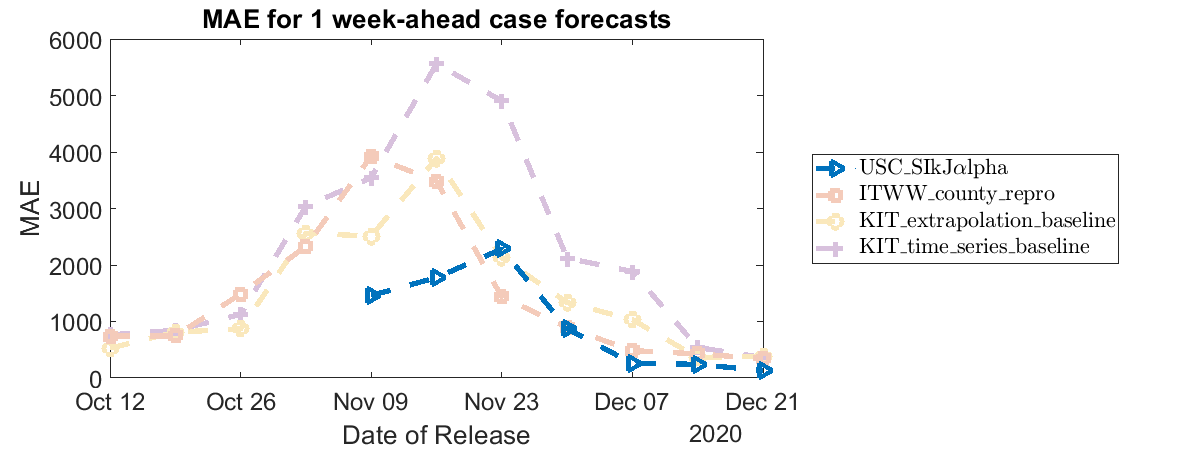

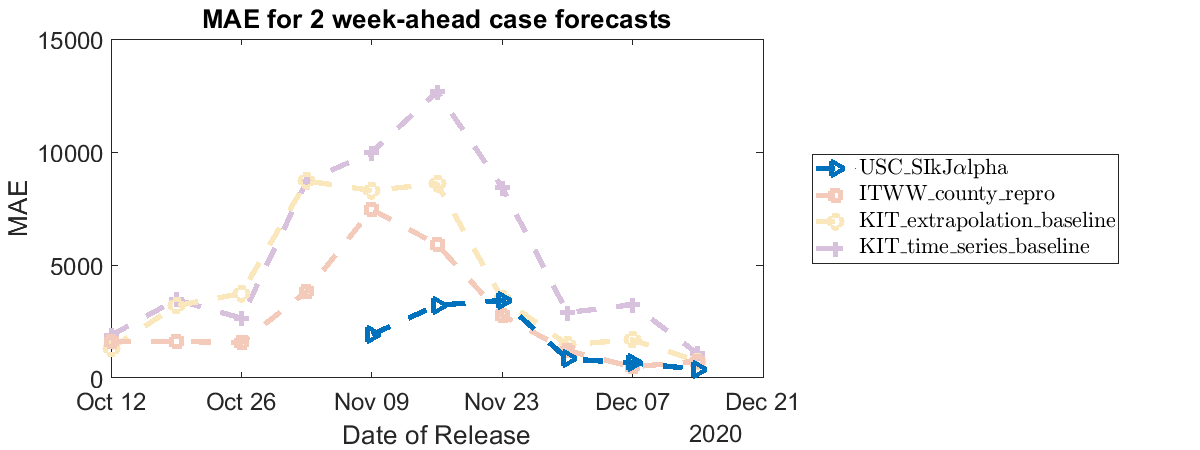

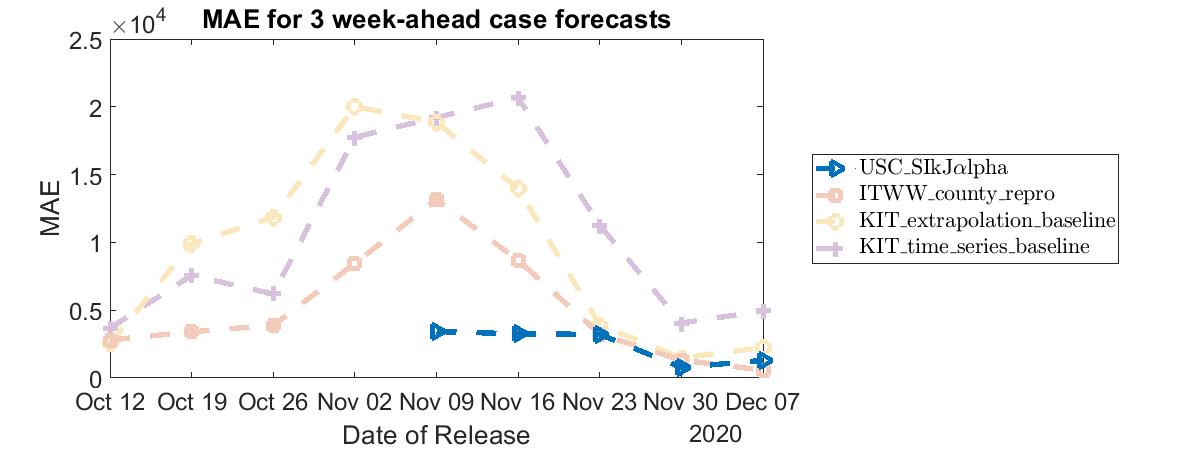

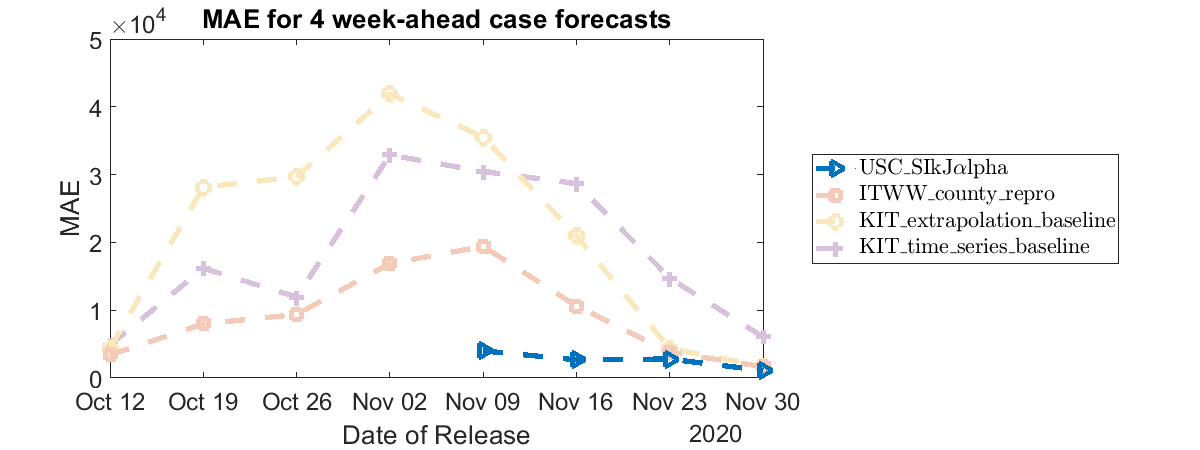

for aidx = 1:4
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    ll = {};
    hh = zeros(length(methods), 1);
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['all_error = case_' methods{mm} ';']);
        errs = nanmean(squeeze(all_error(:, sel_regs, aidx)), 2);
        nnanidx = ~isnan(errs);
        if sum(nnanidx)<1
            continue;
        end
        Tx = base_days;
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{1+mod(mm, 13)}, 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10);
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        hh(mm1) = p1;
        hold on;
        ll = [ll; methods{mm}];
    end
    title(['MAE for ' num2str(aidx) ' week-ahead case forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');

    hold off;
    ll = strrep(ll, '_', '\_');
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    set(gca, 'Children', fliplr(hh(hh>0)));
    ll = get(legend(), 'String');
    plots = flipud(get(gca, 'children'));
    neworder = length(ll):-1:1;
    legend(plots(neworder), ll(neworder)); 
end

## Errors for Germany states death forecasts

Jump to: Poland voivodeships death forecasts; Poland voivodeships case forecasts; Germany states death forecasts; Germany states case forecasts; Poland+Germany country-level death forecasts; Poland+Germany country-level case forecasts;

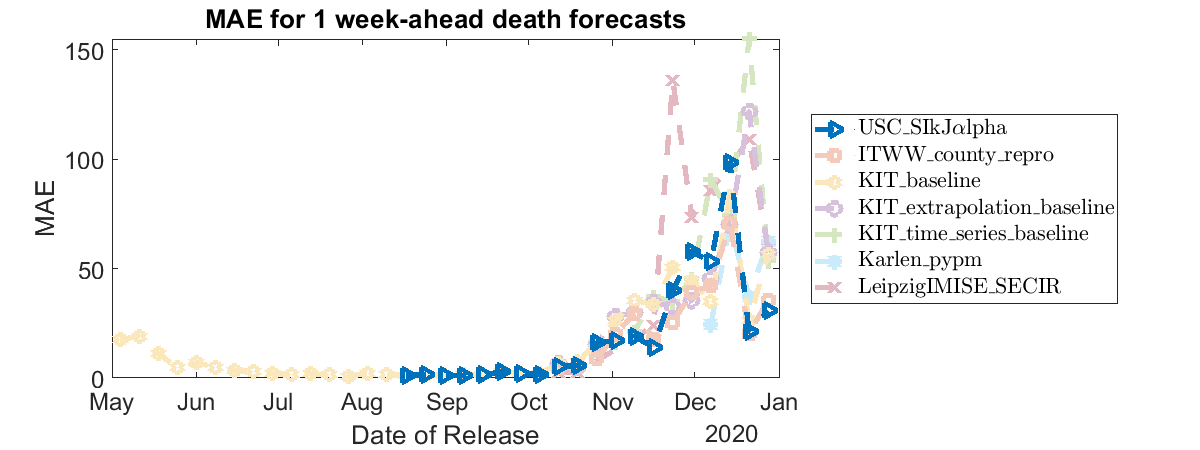

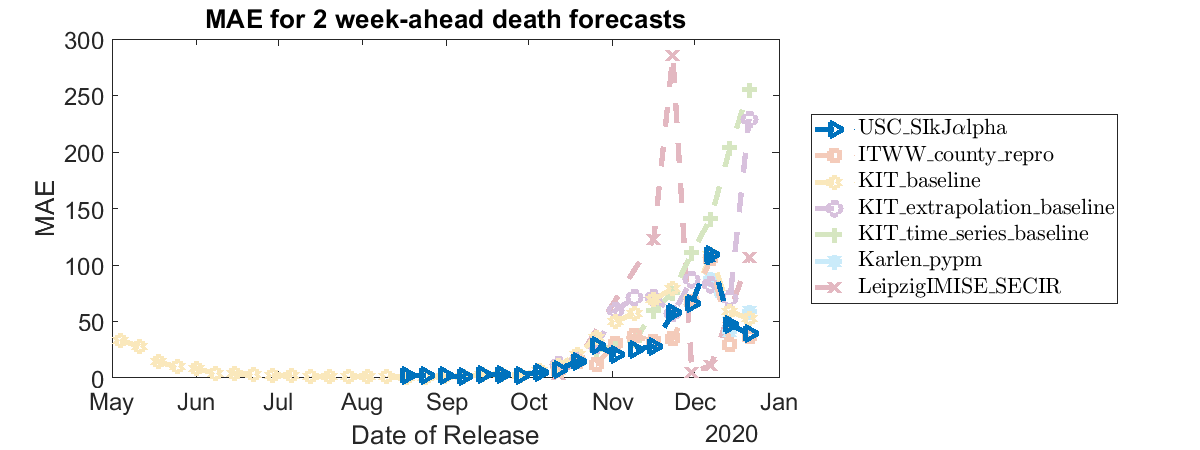

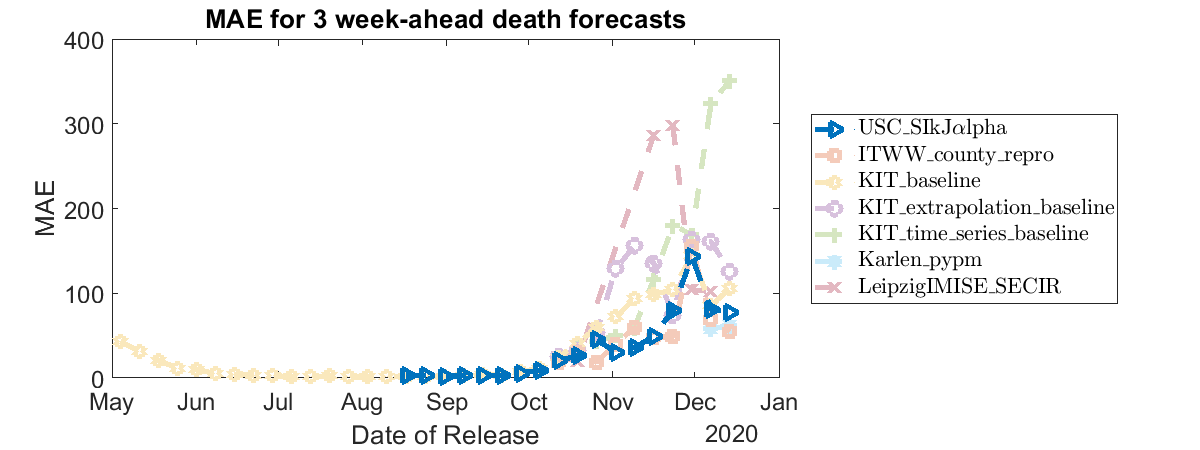

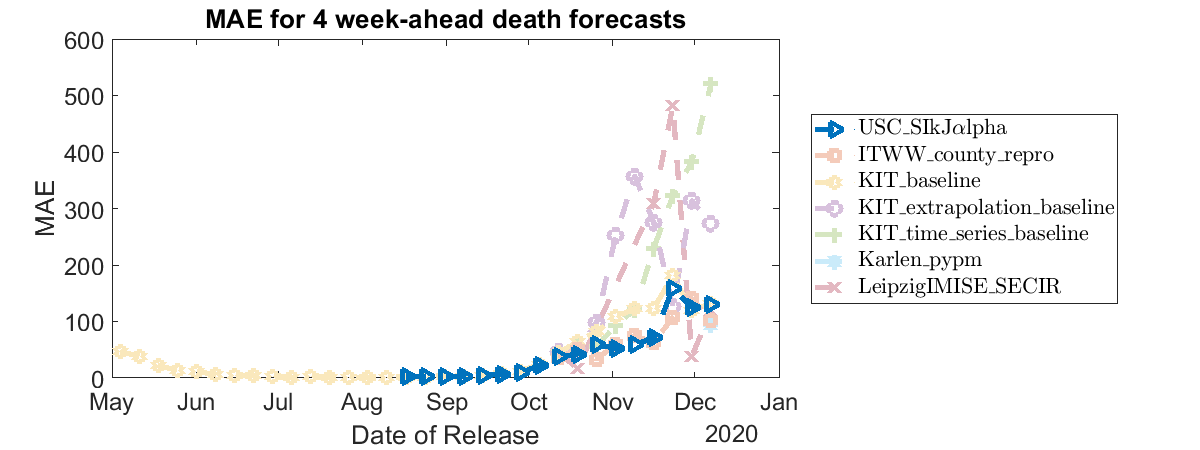

all_marks = {'o','+','*','.','x','s','d','^','v','>','<','p','h'};

sel_regs = contains(countries, 'GM0')|contains(countries, 'GM1');
highlight_idx = 0.3*ones(length(methods), 1);
sel_methods = [find(startsWith(methods, 'USC')); find(contains(methods, 'hub'))];
highlight_idx(sel_methods) = 1;
reorder_idx = [sel_methods; find(highlight_idx<1)];

for aidx = 1:4
    
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    ll = {};
    hh = zeros(length(methods), 1);
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['all_error = death_' methods{mm} ';']);
        errs = nanmean(squeeze(all_error(:, sel_regs, aidx)), 2);
        nnanidx = ~isnan(errs);
        if sum(nnanidx)<1
            continue;
        end
        Tx = base_days;
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{1+mod(mm, 13)}, 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10);
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        hh(mm1) = p1;
        hold on;
        ll = [ll; methods{mm}];
    end
    title(['MAE for ' num2str(aidx) ' week-ahead death forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    

    hold off;
    ll = strrep(ll, '_', '\_');
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    set(gca, 'Children', fliplr(hh(hh>0)));
    ll = get(legend(), 'String');
    plots = flipud(get(gca, 'children'));
    neworder = length(ll):-1:1;
    legend(plots(neworder), ll(neworder)); 
end

## Errors for Germany states case forecasts

Jump to: Poland voivodeships death forecasts; Poland voivodeships case forecasts; Germany states death forecasts; Germany states case forecasts; Poland+Germany country-level death forecasts; Poland+Germany country-level case forecasts;

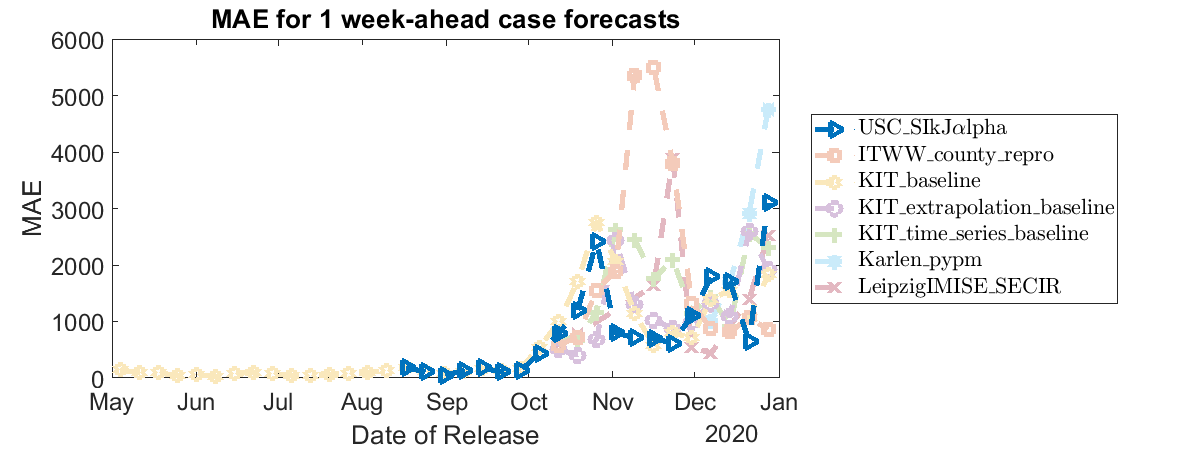

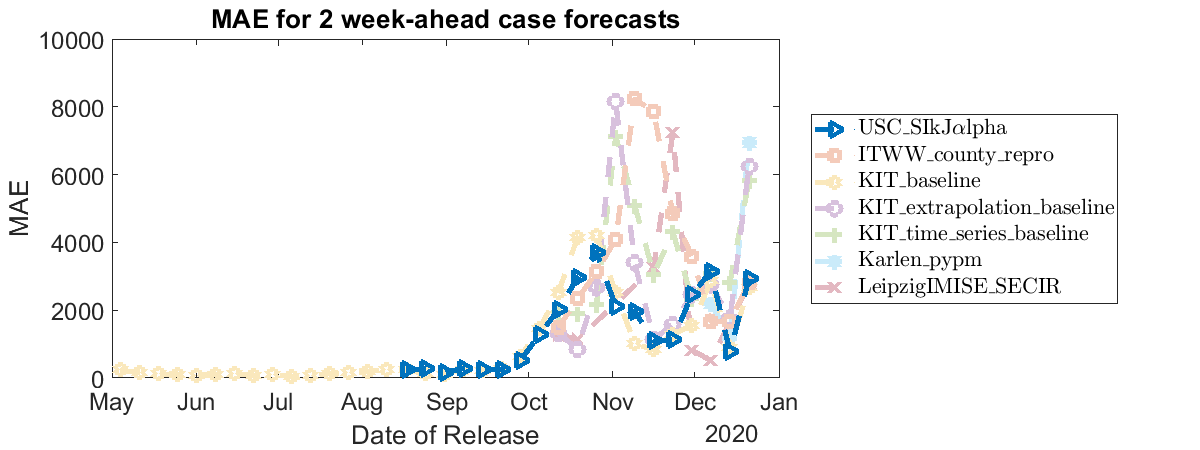

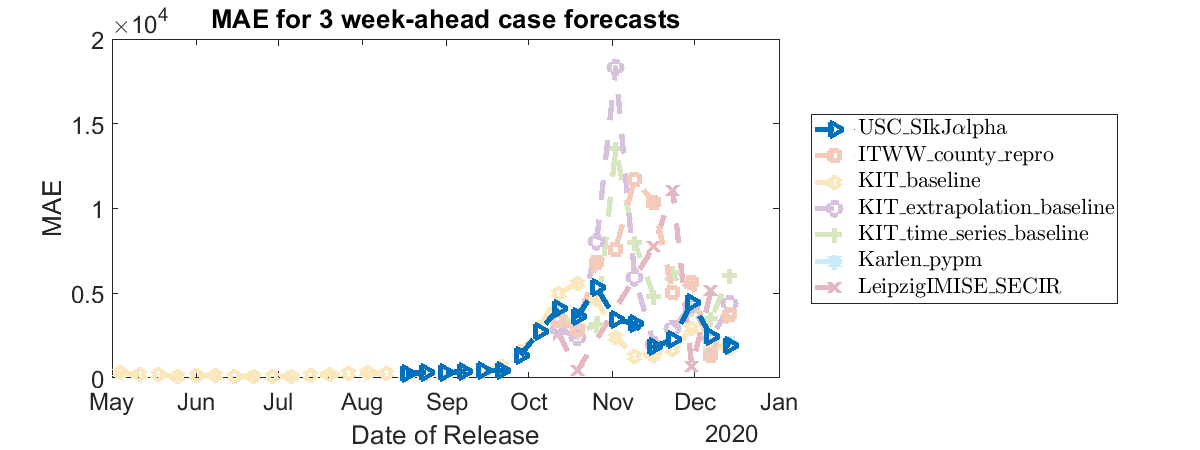

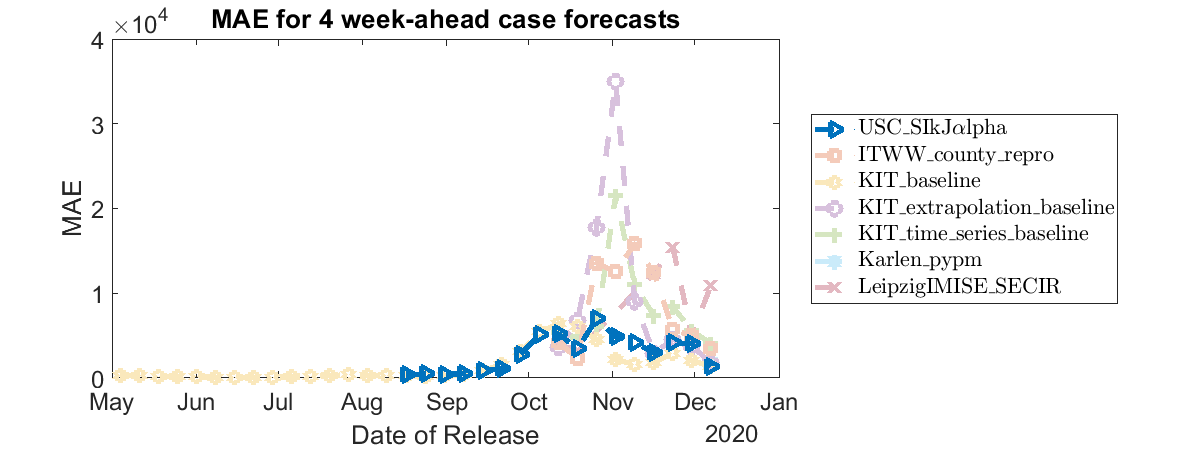


for aidx = 1:4
    
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    ll = {};
    hh = zeros(length(methods), 1);
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['all_error = case_' methods{mm} ';']);
        errs = nanmean(squeeze(all_error(:, sel_regs, aidx)), 2);
        nnanidx = ~isnan(errs);
        if sum(nnanidx)<1
            continue;
        end
        Tx = base_days;
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{1+mod(mm, 13)}, 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10);
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        hh(mm1) = p1;
        hold on;
        ll = [ll; methods{mm}];
    end
    title(['MAE for ' num2str(aidx) ' week-ahead case forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    

    hold off;
    ll = strrep(ll, '_', '\_');
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    set(gca, 'Children', fliplr(hh(hh>0)));
    ll = get(legend(), 'String');
    plots = flipud(get(gca, 'children'));
    neworder = length(ll):-1:1;
    legend(plots(neworder), ll(neworder)); 
end

## Errors for country-level death forecasts

Jump to: Poland voivodeships death forecasts; Poland voivodeships case forecasts; Germany states death forecasts; Germany states case forecasts; Poland+Germany country-level death forecasts; Poland+Germany country-level case forecasts;

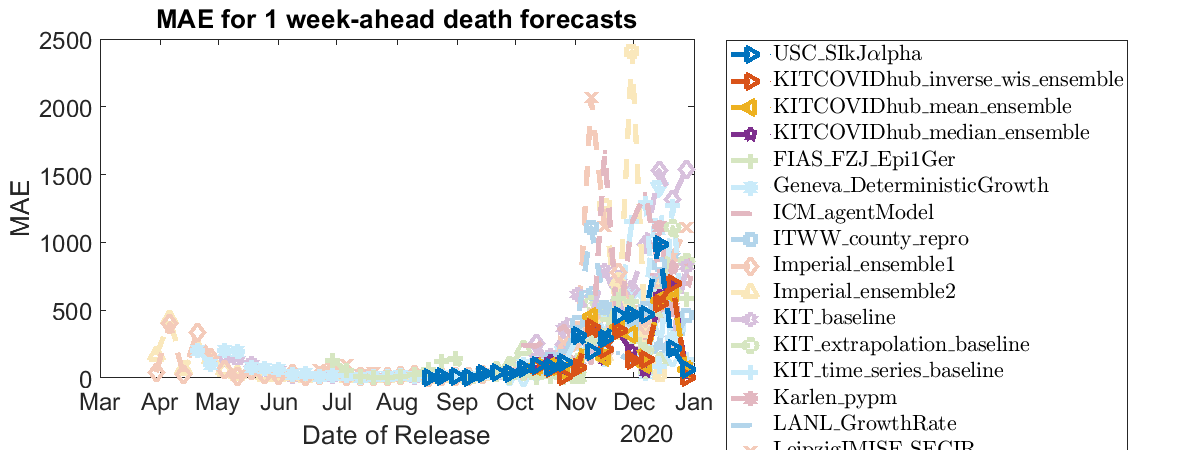

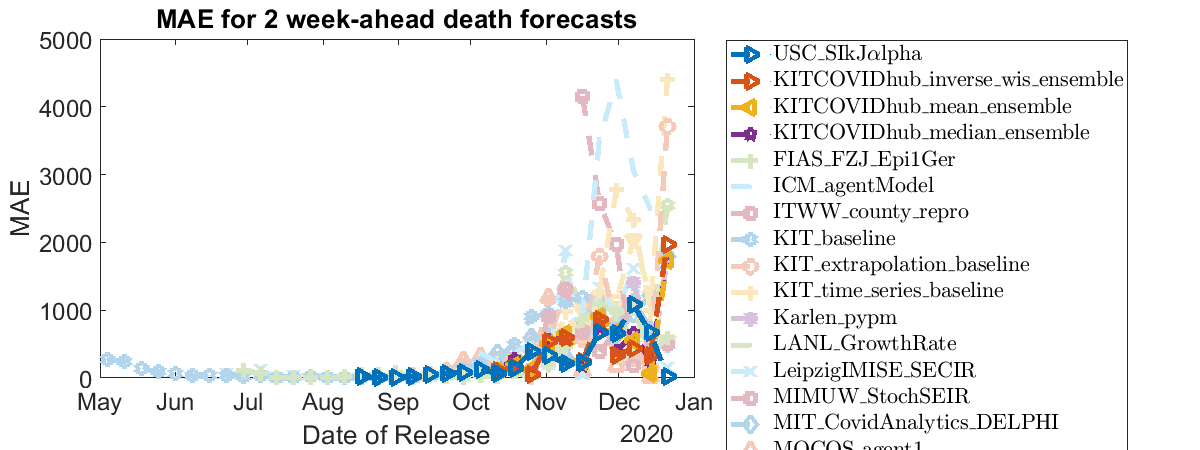

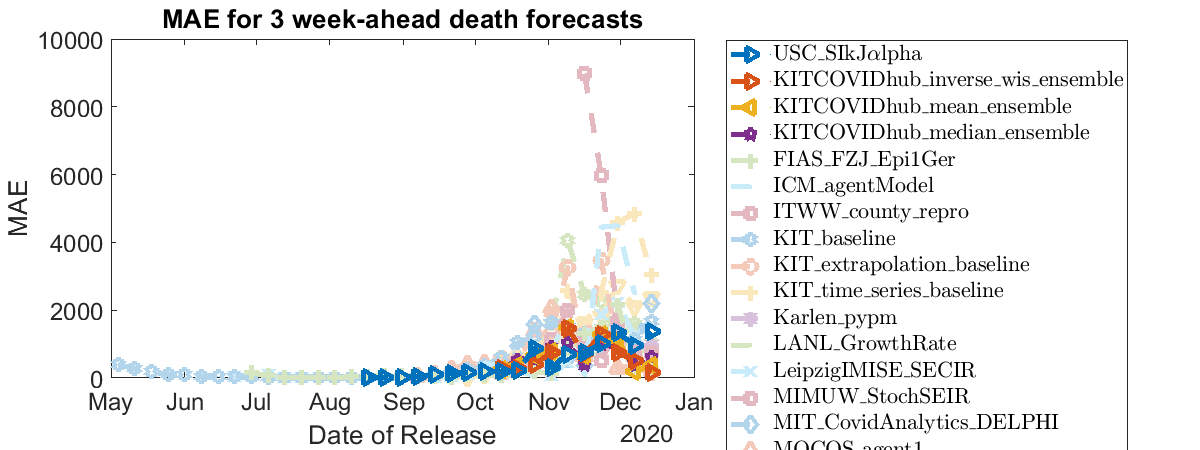

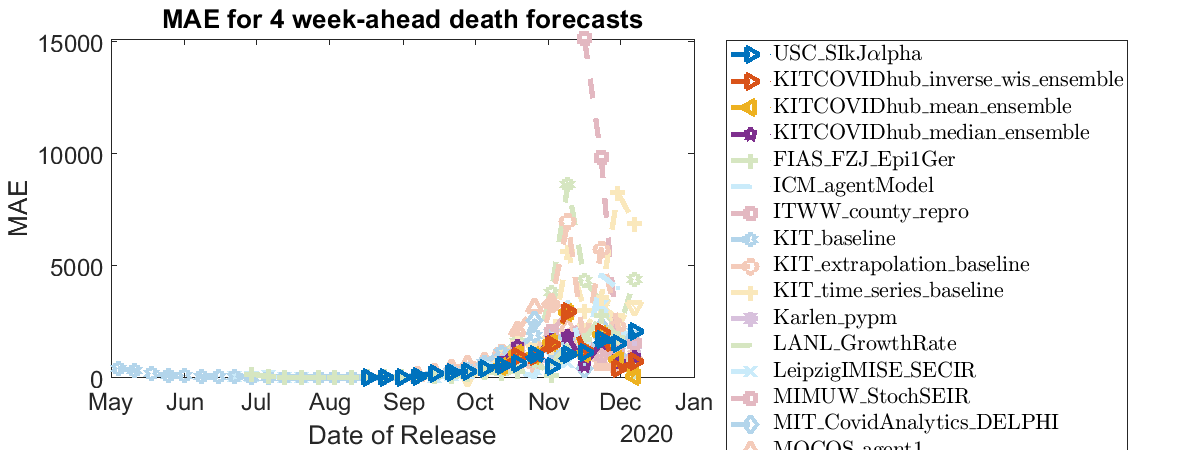

all_marks = {'o','+','*','.','x','s','d','^','v','>','<','p','h'};

sel_regs = strcmp(countries, 'GM')|strcmp(countries, 'PL');
highlight_idx = 0.3*ones(length(methods), 1);
sel_methods = [find(startsWith(methods, 'USC')); find(contains(methods, 'hub'))];
highlight_idx(sel_methods) = 1;
reorder_idx = [sel_methods; find(highlight_idx<1)];

for aidx = 1:4
    
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    ll = {};
    hh = zeros(length(methods), 1);
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['all_error = death_' methods{mm} ';']);
        errs = nanmean(squeeze(all_error(:, sel_regs, aidx)), 2);
        nnanidx = ~isnan(errs);
        if sum(nnanidx)<1
            continue;
        end
        Tx = base_days;
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{1+mod(mm, 13)}, 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10);
        hh(mm1) = p1;
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        hold on;
        ll = [ll; methods{mm}];
    end
    title(['MAE for ' num2str(aidx) ' week-ahead death forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    
    hold off;
    ll = strrep(ll, '_', '\_');
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    set(gca, 'Children', fliplr(hh(hh>0)));
    ll = get(legend(), 'String');
    plots = flipud(get(gca, 'children'));
    neworder = length(ll):-1:1;
    legend(plots(neworder), ll(neworder)); 
end

## Errors for country-level case forecasts

Jump to: Poland voivodeships death forecasts; Poland voivodeships case forecasts; Germany states death forecasts; Germany states case forecasts; Poland+Germany country-level death forecasts; Poland+Germany country-level case forecasts;

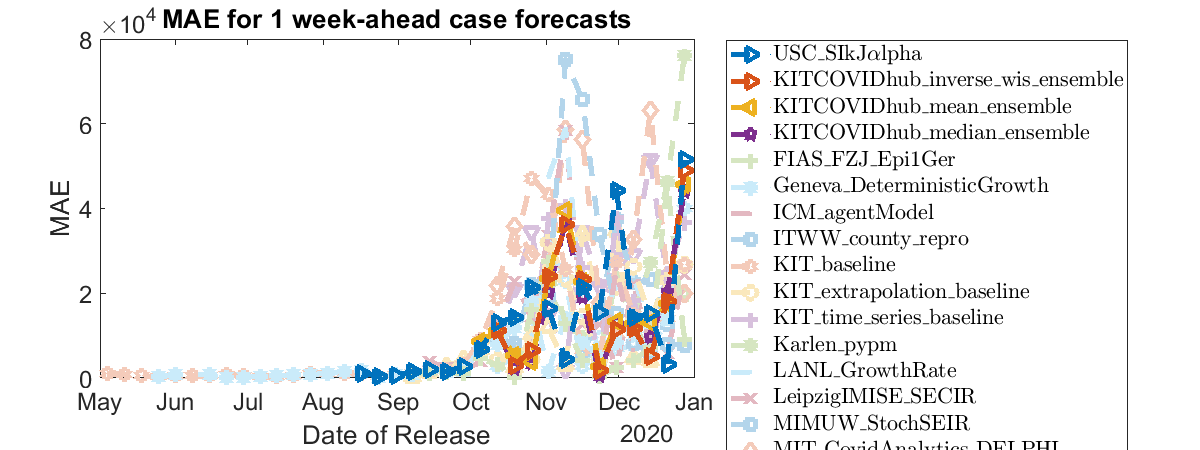

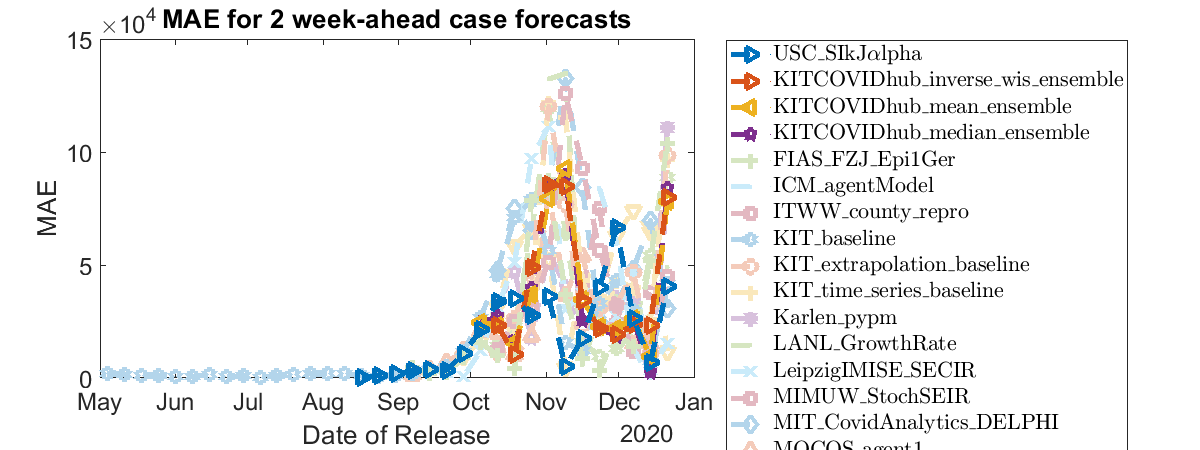

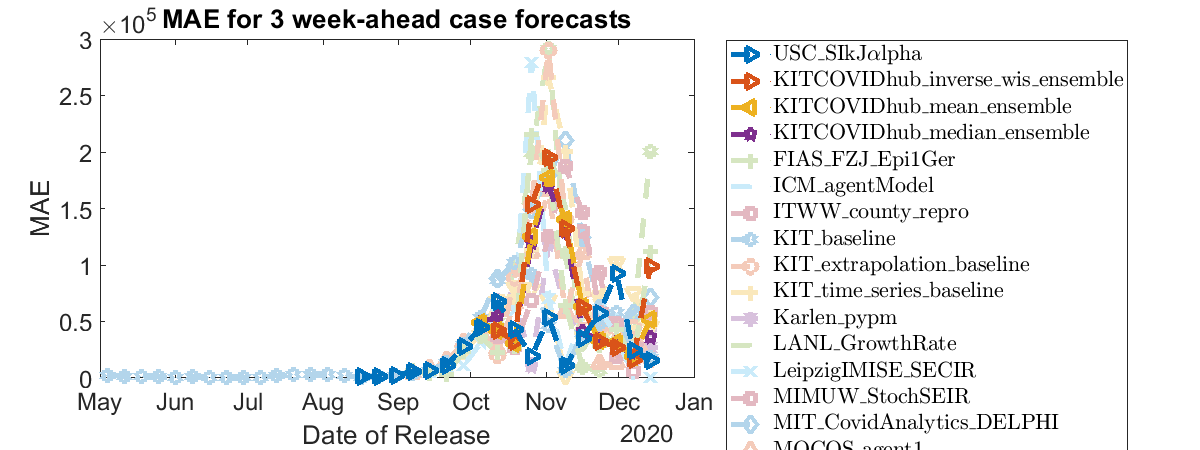

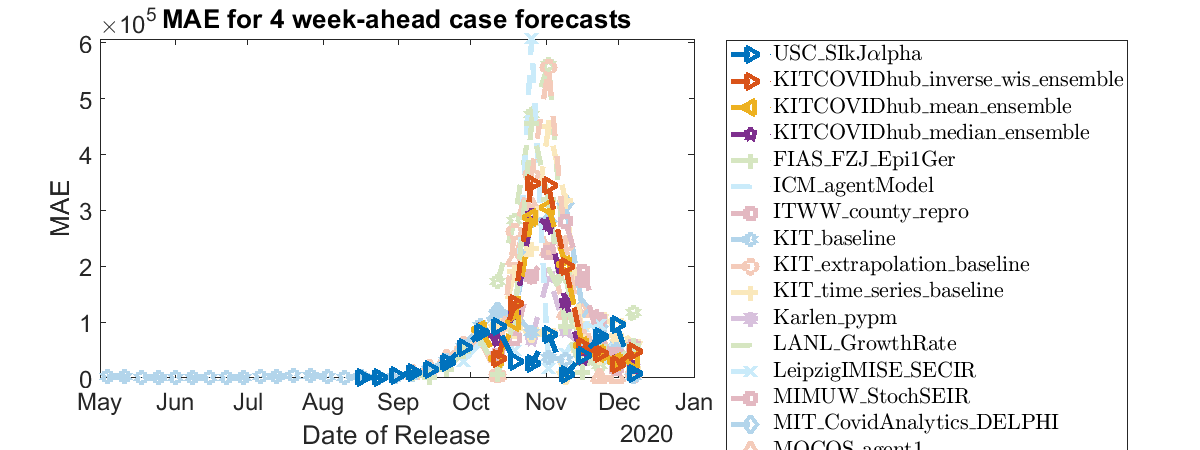


for aidx = 1:4
    
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    ll = {};
    hh = zeros(length(methods), 1);
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['all_error = case_' methods{mm} ';']);
        errs = nanmean(squeeze(all_error(:, sel_regs, aidx)), 2);
        nnanidx = ~isnan(errs);
        if sum(nnanidx)<1
            continue;
        end
        Tx = base_days;
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{1+mod(mm, 13)}, 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10);
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        hh(mm1) = p1;
        hold on;
        ll = [ll; methods{mm}];
    end
    title(['MAE for ' num2str(aidx) ' week-ahead case forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    %uistack(hh, 'top');

    hold off;
    ll = strrep(ll, '_', '\_');
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    set(gca, 'Children', fliplr(hh(hh>0)));
    ll = get(legend(), 'String');
    plots = flipud(get(gca, 'children'));
    neworder = length(ll):-1:1;
    legend(plots(neworder), ll(neworder)); 
end

Jump to: 

Poland voivodeships death forecasts; Poland voivodeships case forecasts;

Germany states death forecasts; Germany states case forecasts; 

Poland+Germany country-level death forecasts; Poland+Germany country-level case forecasts;